Loading data

clear
load('data.mat')

Data filtering

SondaSterujca = data.SondaSterujca;
parownik = data.parownik;
skraplacz = data.skraplacz;
compressor = data.compressor;


Excluding categorical values [i.e compressor]

X=[SondaSterujca,parownik,skraplacz]';

X=X(:,1400:end);

[n,m]=size(X);


Deleating NaN value entries


for k=1:n
    [X1(k,:),~]=GetRidOfNans(X(k,:));
end

Applying a lowpass filter

X2=FilterData(X1);

Finding Cycles

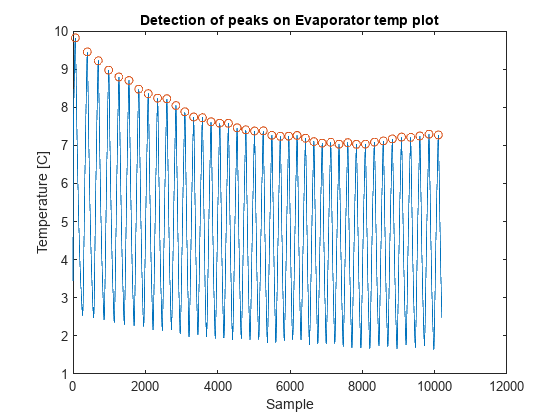

[pks,locs] = findpeaks(X2(2,:));



n=length(X2);
x=1:n;
plot(x,X2(2,:));hold on;
plot(locs,pks,"o");hold off
title('Detection of peaks on Evaporator temp plot')
xlabel('Sample')
ylabel('Temperature [C]')

Features to be found:

1) length of cycle

2) max and min val in the cycle

3) mean

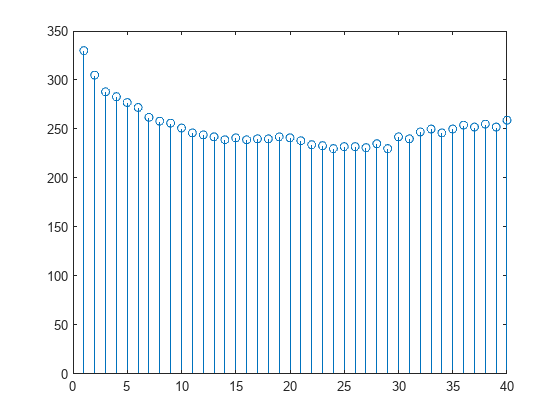

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end

figure
stem(f1)

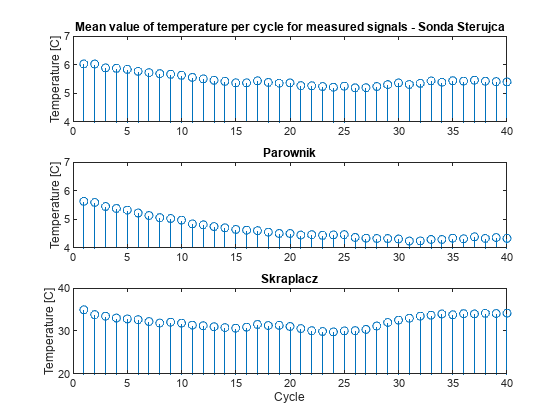


x_SondaSterujca = FeatureExtract(X2(1,:),locs);
x_parownik = FeatureExtract(X2(2,:),locs);
x_skraplacz = FeatureExtract(X2(3,:),locs);

figure

subplot(311)
stem(x_SondaSterujca(3,:))
title('Mean value of temperature per cycle for measured signals - Sonda Sterujca')
ylabel('Temperature [C]')
ylim([4,7])
subplot(312)
stem(x_parownik(3,:))
title('Parownik')
ylabel('Temperature [C]')
ylim([4,7])
subplot(313)
stem(x_skraplacz(3,:))
title('Skraplacz')
xlabel('Cycle')
ylabel('Temperature [C]')
ylim([20,40])

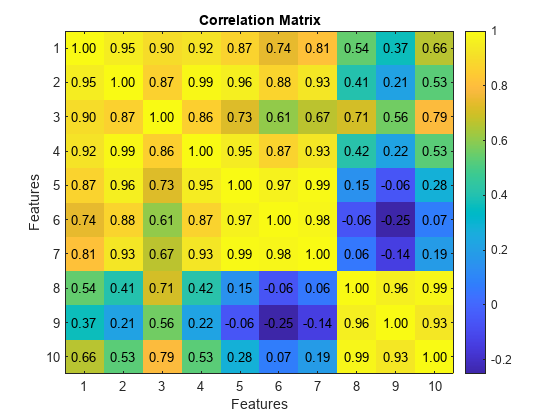

rawMatrix=[f1;x_SondaSterujca;x_parownik;x_skraplacz];

correlationMatrix = corrcoef(rawMatrix');

figure;
imagesc(correlationMatrix);
colorbar;
title('Correlation Matrix');
xlabel('Features');
ylabel('Features');
textColors = repmat(correlationMatrix(:) < 0.5, 1, 3);
textStrings = num2str(correlationMatrix(:), '%0.2f');
textStrings = strtrim(cellstr(textStrings));
[x, y] = meshgrid(1:size(correlationMatrix, 1));
hStrings = text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center', 'Color', 'black');

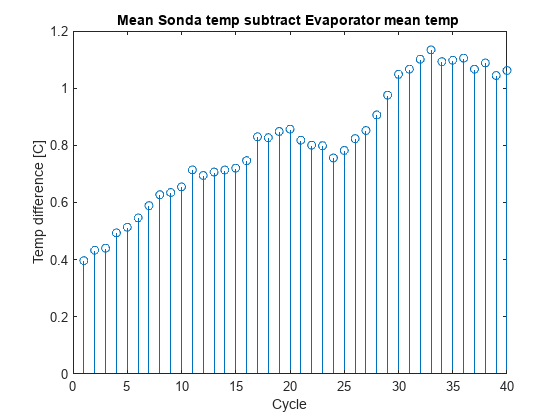

figure
stem(x_SondaSterujca(3,:)-x_parownik(3,:))
title('Mean Sonda temp subtract Evaporator mean temp ')
xlabel('Cycle')
ylabel('Temp difference [C]')